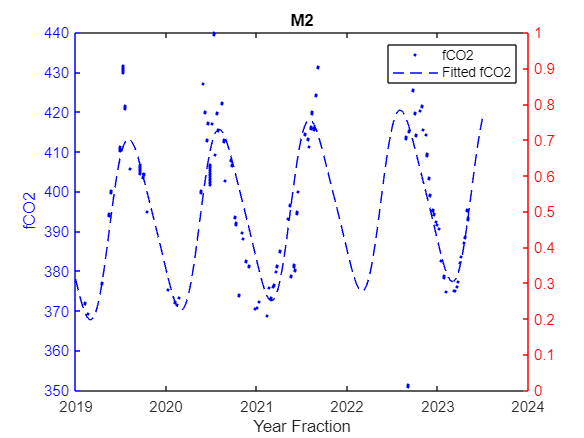

Data inputs must match the axis configuration. A numeric axis must have numeric data inputs or data inputs which can be converted to double.

plot(Ac.Date, Ac.fCO2sw, ".")

plot(Ac.Date, Ac.IntakeTemp, ".r")

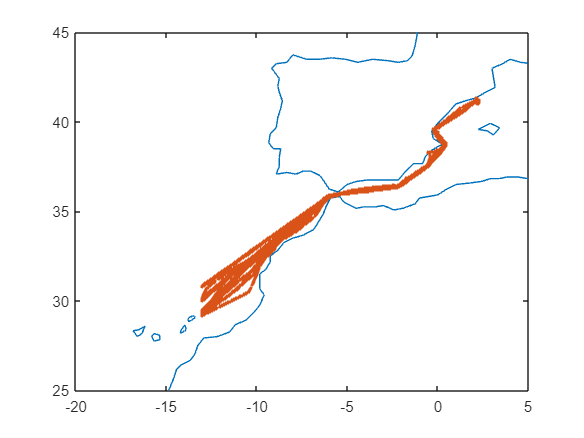

load coastlines.mat
plot(coastlon, coastlat)
hold on
plot(Ac.longitude, Ac.latitude, ".")
hold off
xlim([-20 5])
ylim([25 45])

Ac.latitude(Ac.latitude > 90)= NaN;

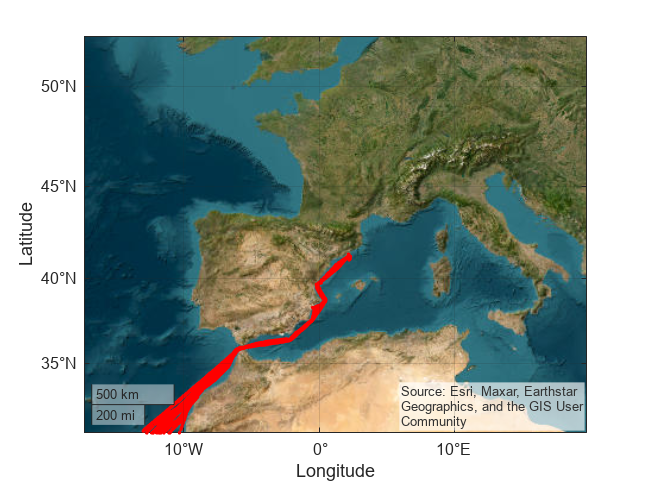

geoplot(Ac.latitude, Ac.longitude, "r.")
geobasemap satellite

Ac.YearFraction = 2019+(Ac.JulianDate-43466)./365.25;

m1a = Ac(Ac.longitude < -11.62 & Ac.longitude > -11.72 & Ac.latitude > 31, :);
m1b = Ac(Ac.longitude < -11.62 & Ac.longitude > -11.72 & Ac.latitude < 31, :);
m2 = Ac(Ac.longitude < -10.01 & Ac.longitude > -10.11 & Ac.latitude > 32.1, :);
m3 = Ac(Ac.longitude < -8.39 & Ac.longitude > -8.49 & Ac.latitude < 34, :);
m4 = Ac(Ac.longitude < -6.89 & Ac.longitude > -6.99 & Ac.latitude > 34.7, :);
m5 = Ac(Ac.longitude < -4.95 & Ac.longitude > -5.05, :);
m6 = Ac(Ac.longitude < -3.75 & Ac.longitude > -3.85, :);
m7 = Ac(Ac.longitude < -1.71 & Ac.longitude > -1.81, :);
m8 = Ac(Ac.longitude < -0.04 & Ac.longitude > -0.14 & Ac.latitude < 38.3, :);
m9 = Ac(Ac.longitude < 0.80 & Ac.longitude > 0.70, :);

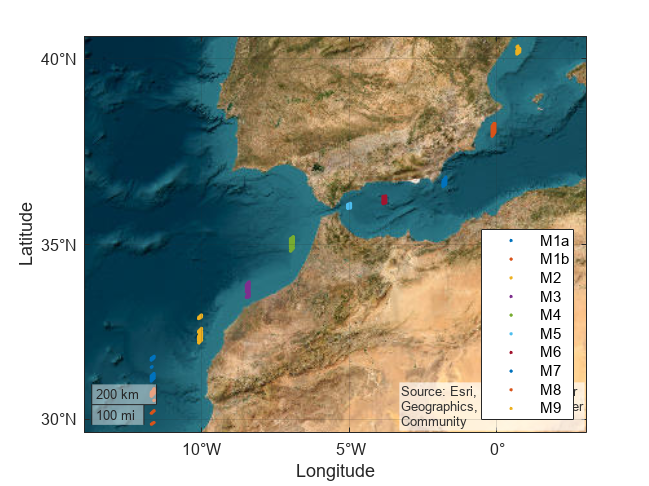

% plot(coastlon, coastlat)
% hold on
geoplot(m1a.latitude, m1a.longitude, ".")
hold on
geoplot(m1b.latitude, m1b.longitude, ".")
hold on
geoplot(m2.latitude, m2.longitude, ".")
hold on
geoplot(m3.latitude, m3.longitude, ".")
hold on
geoplot(m4.latitude, m4.longitude, ".")
hold on
geoplot(m5.latitude, m5.longitude, ".")
hold on
geoplot(m6.latitude, m6.longitude, ".")
hold on
geoplot(m7.latitude, m7.longitude, ".")
hold on
geoplot(m8.latitude, m8.longitude, ".")
hold on
geoplot(m9.latitude, m9.longitude, ".")
hold off
% xlim([-20 5])
% ylim([25 45])
legend(["M1a", "M1b", "M2", "M3", "M4", "M5", "M6", "M7", "M8", "M9"], "Location","southeast")

geobasemap satellite

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m1.YearFraction, m1.fCO2sw, "b.")
title("M1")
hold on
plot(fitM1, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m1.YearFraction, m1.IntakeTemp, ".r")
hold on
plot(fitM1t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

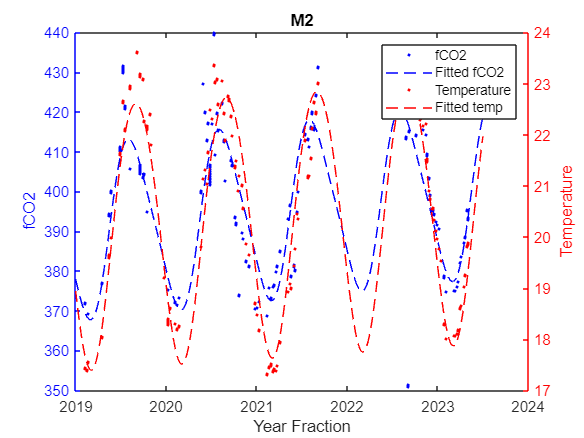

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m2.YearFraction, m2.fCO2sw, "b.")
hold on
plot(fitM2, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m2.YearFraction, m2.IntakeTemp, ".r")
title("M2")
hold on
plot(fitM2t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m3.YearFraction, m3.fCO2sw, "b.")
hold on
plot(fitM3, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m3.YearFraction, m3.IntakeTemp, ".r")
title("M3")
hold on
plot(fitM3t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m4.YearFraction, m4.fCO2sw, "b.")
hold on
plot(fitM4, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m4.YearFraction, m4.IntakeTemp, ".r")
title("M4")
hold on
plot(fitM4t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m5.YearFraction, m5.fCO2sw, "b.")
hold on
plot(fitM5, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m5.YearFraction, m5.IntakeTemp, ".r")
title("M5")
hold on
plot(fitM5t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m6.YearFraction, m6.fCO2sw, "b.")
hold on
plot(fitM6, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m6.YearFraction, m6.IntakeTemp, ".r")
title("M6")
hold on
plot(fitM6t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m7.YearFraction, m7.fCO2sw, "b.")
hold on
plot(fitM7, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m7.YearFraction, m7.IntakeTemp, ".r")
title("M7")
hold on
plot(fitM7t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

fig = figure;
left_color = [0 0 1];
right_color = [1 0 0];
set(fig,'defaultAxesColorOrder',[left_color; right_color]);

yyaxis left
plot(m8.YearFraction, m8.fCO2sw, "b.")
hold on
plot(fitM8, "b")
hold off
ylabel("fCO2")
xlabel("Year Fraction")

yyaxis right
plot(m8.YearFraction, m8.IntakeTemp, ".r")
title("M8")
hold on
plot(fitM8t, "r")
hold off
ylabel("Temperature")
xlabel("Year Fraction")
legend("fCO2", "Fitted fCO2", "Temperature", "Fitted temp")

